load('85350.mat');
%load('PolarizedSimulationResult.mat');
addpath('../Library');
mli=9.988346*10^-27;  %kg
hbar=1.0545718*10^(-34); %SI
hh=2*pi*hbar;%SI Planck constant
omega=23.9*2*pi; %in rad/s
pixellength=1.44*10^-6; %in m
sigma0=0.215*10^-12/2; %in m^2
Nsat=330; %PI Camera
warning('off','all');
[ KappaTildeT_Pol, PTildeT_Pol,TTildeT_Pol] = IdealFermiEOS( 1,6, 5000 );
Xdash=0.1:0.05:6;
Ydash=1./Xdash;
[ KappaTildeT_U, PTildeT_U, TTildeT_U, ~, ~] = ...
    VirialUnitarity( );

p1=errorbar(Ptbin,KtMean,KtStd);
set(p1,'DisplayName','EoS Data from Experiment, Unitary',...
    'MarkerSize',3,...
    'MarkerFaceColor',[1 1 0],...
    'Marker','diamond',...
    'LineStyle','none',...
    'Color',[1 0 0])
hold on
p2=plot(Xdash,Ydash,'k--');
set(p2,'DisplayName','KappaTilde*PTilde=1');
p3=plot(PTildeT_U,KappaTildeT_U);
set(p3,'DisplayName','Virial Expansion 3rd order','LineWidth',3,...
    'Color',[0 0.447058826684952 0.74117648601532]);
p4=scatter(Ptbin_Pol,KtMean_Pol,'k*');
set(p4,'DisplayName','Simulated Polarized Fermi Gas EoS')
p5=plot(PTildeT_Pol,KappaTildeT_Pol,'linewidth',3);
set(p5,'DisplayName','Ideal Polarized Fermi Gas EoS')
xlim([0,4]);
ylim([0,4]);
xlabel('P/P_0');ylabel('\kappa/\kappa_0');
legend('show');
hold off

PtU=Ptbin;
KtU=KtMean;
% the cutoff value for the pressure.
Ptcutoff=4;
Ttcutoff=interp1(PTildeT_U,TTildeT_U,Ptcutoff);

KtU(PtU>Ptcutoff)=[];
PtU(PtU>Ptcutoff)=[];
PtU(isnan(KtU))=[];
KtU(isnan(KtU))=[];

TtU=GetTTilde(PtU,KtU,Ttcutoff);
p1=scatter(TtU,KtU,'DisplayName','Experiment Data Unitary');
hold on
pbaspect([1 0.5 1])
plot(TTildeT_U,KappaTildeT_U,'r','linewidth',3,'DisplayName','Virial Expansion 3rd order');
xlabel('T/T_F');
ylabel('\kappa/\kappa_0')
title('\kappa/\kappa_0 vs T/T_F');
xlim([0,1.5])
p3=line([0.17,0.17],[0,3],'linewidth',1,'DisplayName','Tc=0.17');
scatter(Tt_pol,KtMean_Pol,'DisplayName','Simulated Polarize Gas')
plot(TTildeT_Pol,KappaTildeT_Pol,'DisplayName','Ideal Polarize Gas','linewidth',3)
legend('show');
hold off

%%Try to get C_V with P,Kappa and T
Cvt_PKTU = GetCvTilde( PtU,KtU,TtU );
Cvt_PKTU = Cvt_PKTU;
scatter(TtU,Cvt_PKTU,'DisplayName','Experiment Data Unitary with Some Cheating');
hold on
CvTildeT_U=GetCvTilde( PTildeT_U,KappaTildeT_U,TTildeT_U );
plot(TTildeT_U,CvTildeT_U,'DisplayName','Virial Expansion','linewidth',3);
pbaspect([1 0.5 1])
ylim([0,4]);xlim([0,1.5]);
xlabel('T/T_F');
ylabel('C_V/(k_B N)');
scatter(Tt_pol,CvTilde_Sim_Pol,'k*','DisplayName','Simulated Polarized Gas');
plot(TTildeT,CvTildeT_Pol,'DisplayName','Ideal Polarized Gas','LineWidth',3);
title('C_V get from PTilde,kappaTilde,TTilde');
line([0.17,0.17],[0,3],'linewidth',1,'DisplayName','Tc=0.17');
legend('show');
hold off

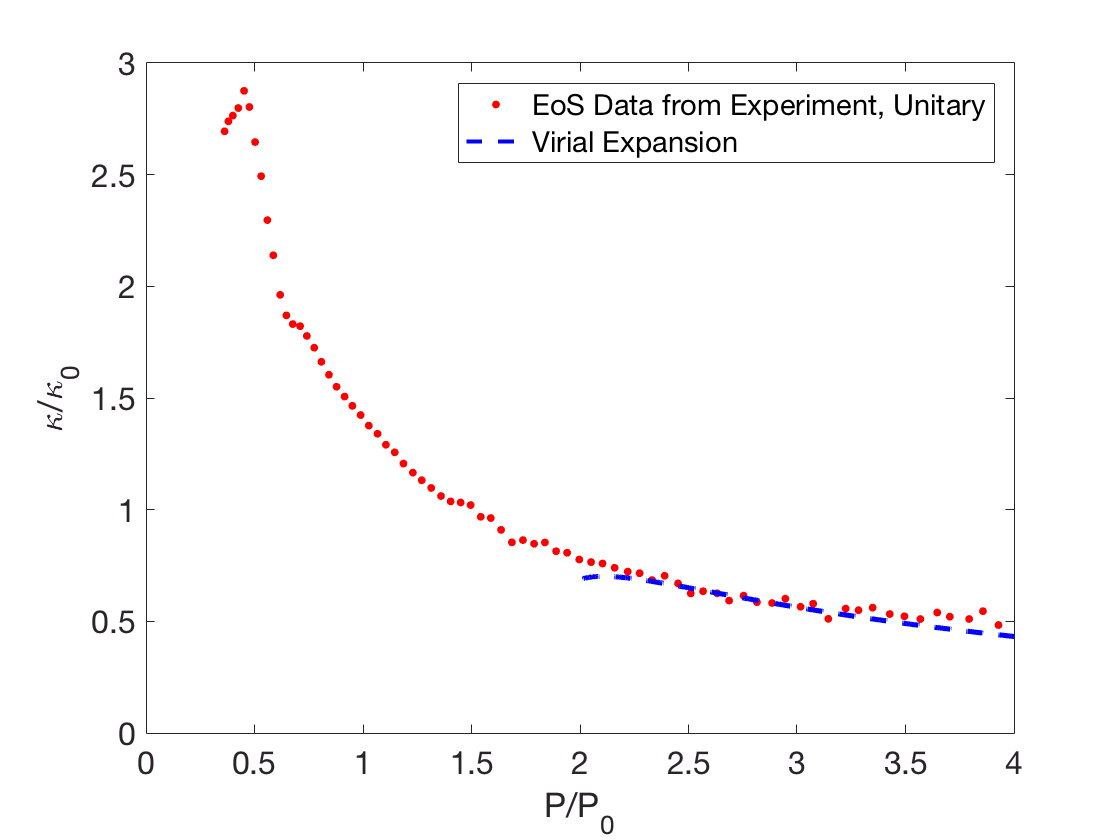

load('85350.mat');
Ptgrid=linspace(sqrt(0.3),sqrt(6),101).^2;
[Ptbin,KtMean,~,KtStd]=BinGrid(Ptlist,Ktlist,Ptgrid,5);
figure('Name','Figure');

% Create axes
axes1 = axes;
p1=plot(Ptbin,KtMean,'DisplayName','EoS Data from Experiment, Unitary',...
    'Markersize',20,...
    'MarkerFaceColor',[1 1 0],...
    'Marker','.','color','r',...
    'LineStyle','none');
hold on
p3=plot(PTildeT_U,KappaTildeT_U,'b--','linewidth',2,'DisplayName','Virial Expansion');
hold off
xlim([0,4])
% Create xlabel
xlabel('P/P_0','FontSize',20);

% Create ylabel
ylabel('\kappa/\kappa_0','FontSize',20);

% Uncomment the following line to preserve the X-limits of the axes
% xlim(axes1,[0 3.75]);
box(axes1,'on');
% Set the remaining axes properties
set(axes1,'FontSize',16);
legend1=legend('show');

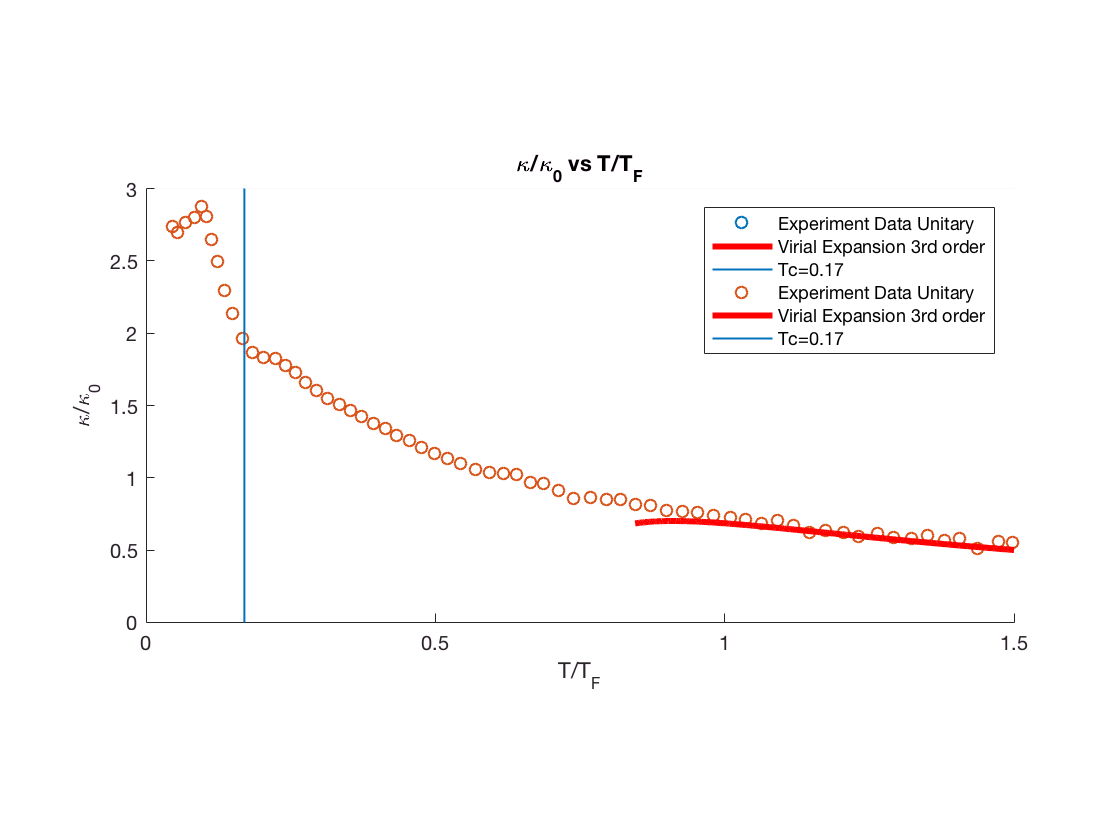

PtU=Ptbin;
KtU=KtMean;
% the cutoff value for the pressure.
Ptcutoff=4;
Ttcutoff=interp1(PTildeT_U,TTildeT_U,Ptcutoff);

KtU(PtU>Ptcutoff)=[];
PtU(PtU>Ptcutoff)=[];
PtU(isnan(KtU))=[];
KtU(isnan(KtU))=[];

TtU=GetTTilde(PtU,KtU,Ttcutoff);
p1=scatter(TtU,KtU,'DisplayName','Experiment Data Unitary');
hold on
pbaspect([1 0.5 1])
plot(TTildeT_U,KappaTildeT_U,'r','linewidth',3,'DisplayName','Virial Expansion 3rd order');
xlabel('T/T_F');
ylabel('\kappa/\kappa_0')
title('\kappa/\kappa_0 vs T/T_F');
xlim([0,1.5])
p3=line([0.17,0.17],[0,3],'linewidth',1,'DisplayName','Tc=0.17');
legend('show');
hold off

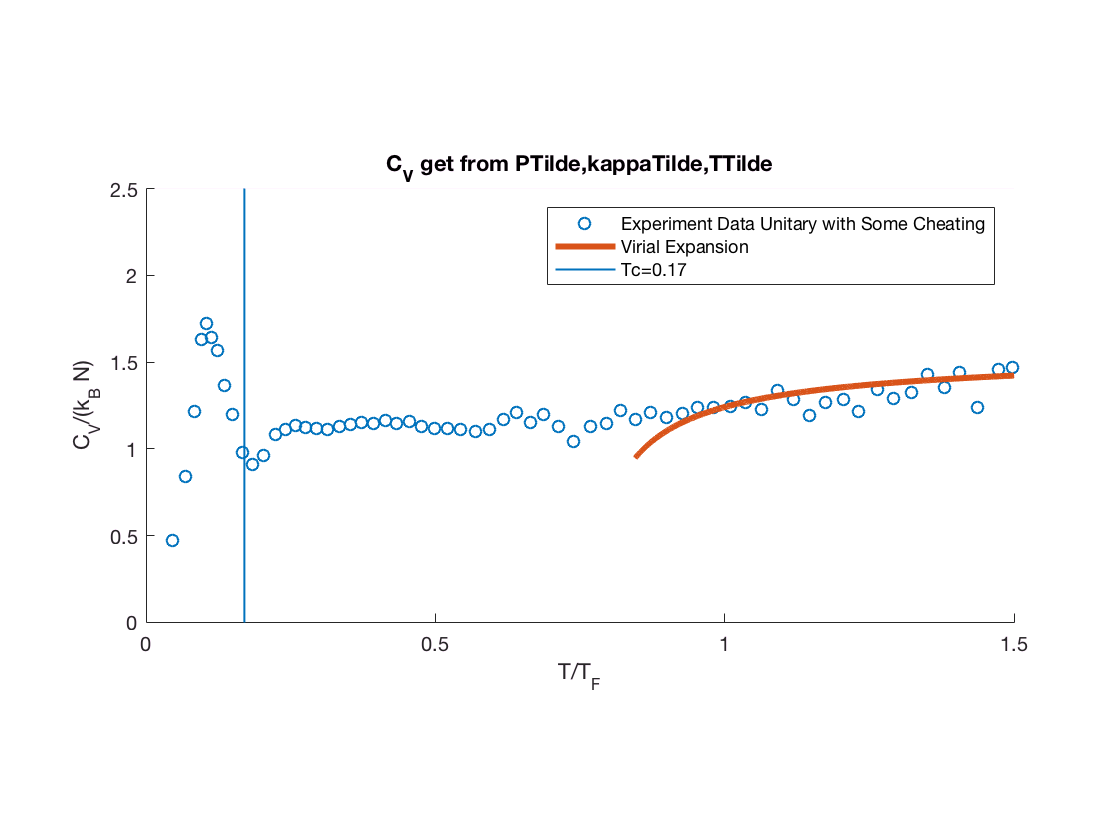

%%Try to get C_V with P,Kappa and T
Cvt_PKTU = GetCvTilde( PtU,KtU,TtU );
Cvt_PKTU = Cvt_PKTU;
scatter(TtU,Cvt_PKTU,'DisplayName','Experiment Data Unitary with Some Cheating');
hold on
CvTildeT_U=GetCvTilde( PTildeT_U,KappaTildeT_U,TTildeT_U );
plot(TTildeT_U,CvTildeT_U,'DisplayName','Virial Expansion','linewidth',3);
pbaspect([1 0.5 1])
ylim([0,2.5]);xlim([0,1.5]);
xlabel('T/T_F');
ylabel('C_V/(k_B N)');
title('Specific Heat');
line([0.17,0.17],[0,3],'linewidth',1,'DisplayName','Tc=0.17');
legend('show');
hold off